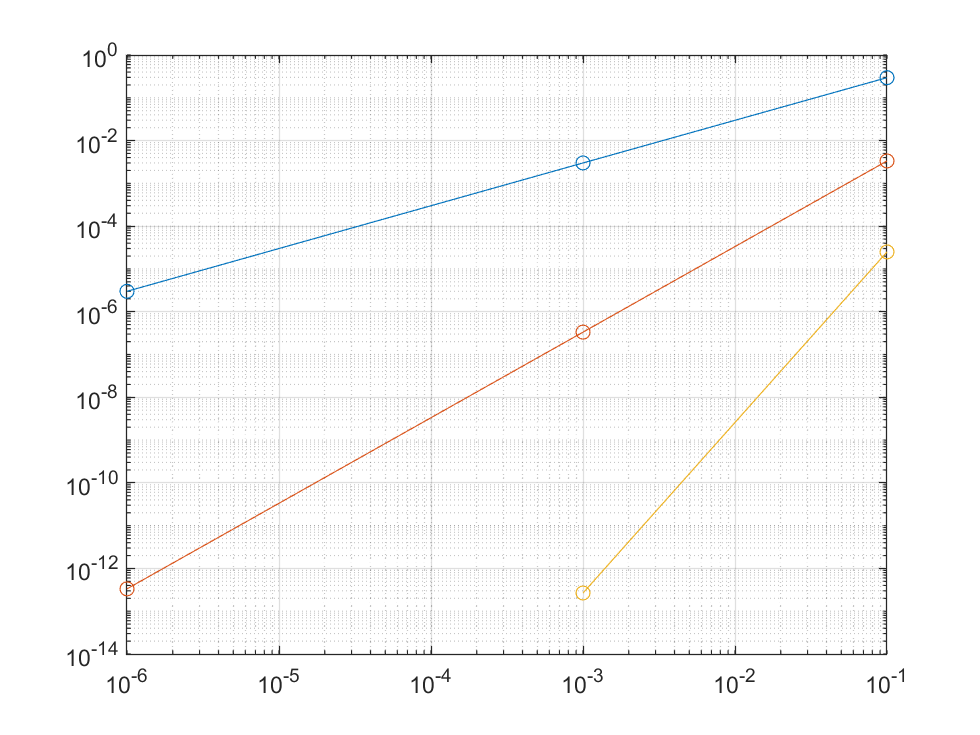

f =@(x) (x.^2-3.*x+2).*atan(x);
fp =@(x) (2.*x-3).*atan(x)+(x.^2-3.*x+2).*(1./(1+x.^2));
x = 0;

h =@(n) (10.^(-n));
n = [1,3,6];

eans = fp(x);

FD1 = forward_diff(f,x,h,n(1,1));
FD3 = forward_diff(f,x,h,n(1,2));
FD6 = forward_diff(f,x,h,n(1,3));

CD31 = centered_diff_3pt(f,x,h,n(1,1));
CD33 = centered_diff_3pt(f,x,h,n(1,2));
CD36 = centered_diff_3pt(f,x,h,n(1,3));

CD51 = centered_diff_5pt(f,x,h,n(1,1));
CD53 = centered_diff_5pt(f,x,h,n(1,2));
CD56 = centered_diff_5pt(f,x,h,n(1,3));

h = h(n);

err1 = [abs(eans-FD1),abs(eans-FD3),abs(eans-FD6)];
err2 = [abs(eans-CD31),abs(eans-CD33),abs(eans-CD36)];
err3 = [abs(eans-CD51),abs(eans-CD53),abs(eans-CD56)];

loglog(h,err1,'o-',h,err2,'o-',h,err3,'o-');
grid on;


% The error appears to be decreasing as h increases as there are more subintervals.
% The largest error is given by the forward difference formula, whereas the smallest
% error is given by 5pt centered difference formula. This is the result of a greater
% usage of points between the formulas to estimate the derivative of the function.


function [fp] = forward_diff(f,x,h,n)
    fp = (f(x+h(n))-f(x))./(h(n));
end

function [fp] = centered_diff_3pt(f,x,h,n)
    fp = (f(x+h(n))-f(x-h(n)))./(2.*h(n));
end

function [fp] = centered_diff_5pt(f,x,h,n)
    fp = (-f(x+2.*h(n))+8.*f(x+h(n))-8.*f(x-h(n))+f(x-2.*h(n)))./(12.*h(n));
end
